Part 1 TODO (Remove before submission):

- Figure out what y_i_plus1 needs to be

- Understand conceptually how to solve a system of differential equations (with RK method)

# MAE 384 Group Project

### Team: Sicko Code

### Contributors: Hayden Redmond, Ottavia Formicone, Brady Bauer, Ava Masche

## Part 1: Modeling disease spread using SIR model

            
$$\begin{array}{l}
\textrm{Susceptible}\;\textrm{individuals}:\;\frac{\textrm{dS}\left(t\right)}{\textrm{dt}}=-\frac{\beta }{N}S\left(t\right)I\left(t\right)\\
\textrm{Infected}\;\textrm{individuals}:\;\;\;\;\;\;\;\;\;\frac{\textrm{dI}\left(t\right)}{\textrm{dt}}=\frac{\beta }{N}S\left(t\right)I\left(t\right)-\gamma I\left(t\right)\\
\textrm{Recovered}\;\textrm{individuals}:\;\;\;\frac{\textrm{dR}\left(t\right)}{\textrm{dt}}=\gamma I\left(t\right)\\
\textrm{Total}\;\textrm{population}:\;\;\;\;\;\;\;\;\;\;\;\;\;\;N=S\left(t\right)+I\left(t\right)+R\left(t\right)\\
\\
\beta =\textrm{transmission}\;\textrm{rate}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\gamma =\textrm{recovery}\;\textrm{rate}
\end{array}$$


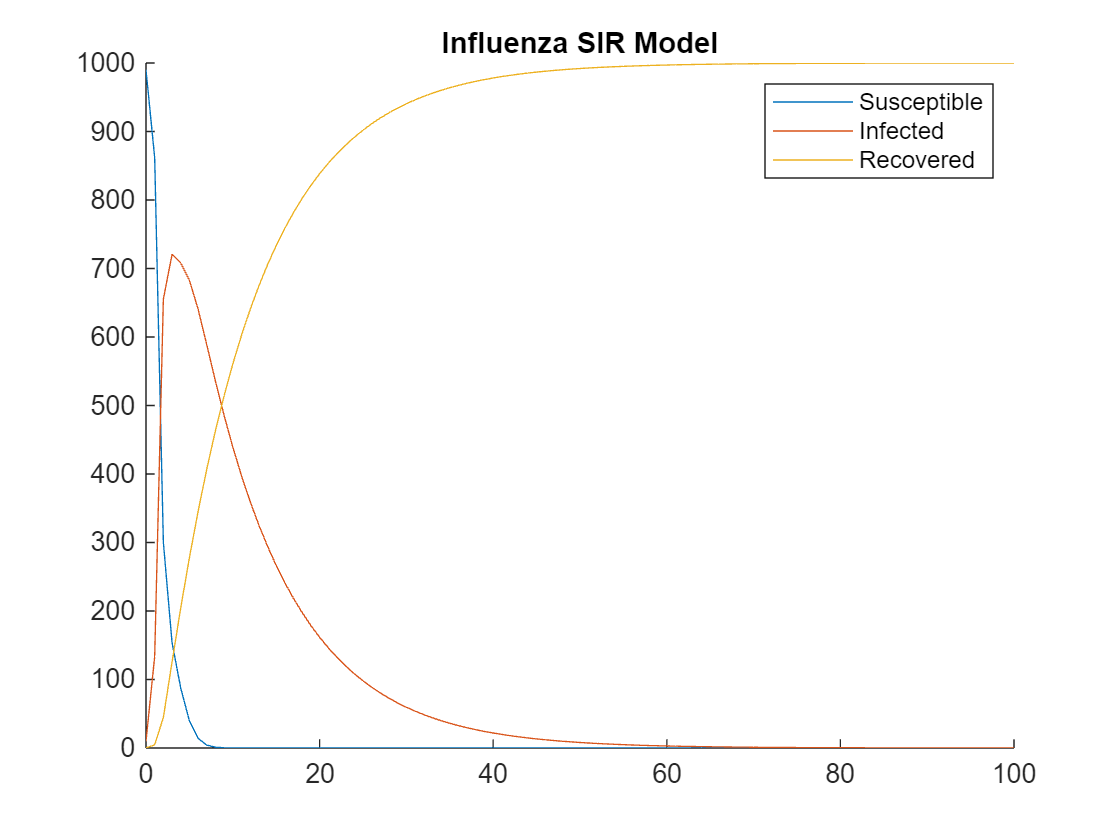

clear; clc; close all
Influenza_Tran_Rate = 0.3;
Influenza_Recov_Rate = 0.1;

COVID_19_Tran_Rate = 1;
COVID_19_Recov_Rate = 0.1;

Measles_Tran_Rate = 2;
Measles_Recov_Rate = 0.2;

[Flu_S,Flu_I,Flu_R] = SIR_Model(990,10,0,100,1,Influenza_Tran_Rate,Influenza_Recov_Rate);
[COVID_S,COVID_I,COVID_R] = SIR_Model(990,10,0,100,1,COVID_19_Tran_Rate,COVID_19_Recov_Rate);
[Measles_S,Measles_I,Measles_R] = SIR_Model(990,10,0,100,1,Measles_Tran_Rate,Measles_Recov_Rate);

Time_Step_1Day = 0:1:100;

figure(1)
hold on
title('Influenza SIR Model')
plot(Time,Flu_S)
plot(Time,Flu_I)
plot(Time,Flu_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000])
hold off

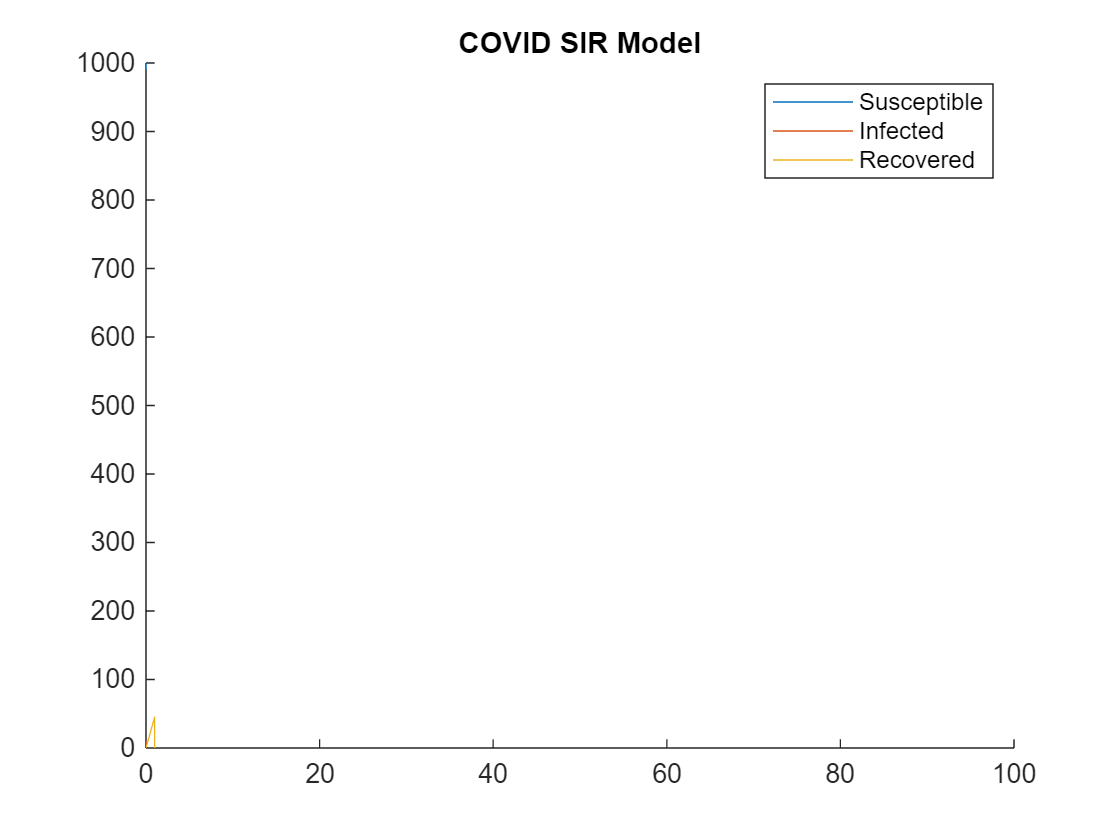

figure(2)
hold on
title('COVID SIR Model')
plot(Time,COVID_S)
plot(Time,COVID_I)
plot(Time,COVID_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000]) 
hold off

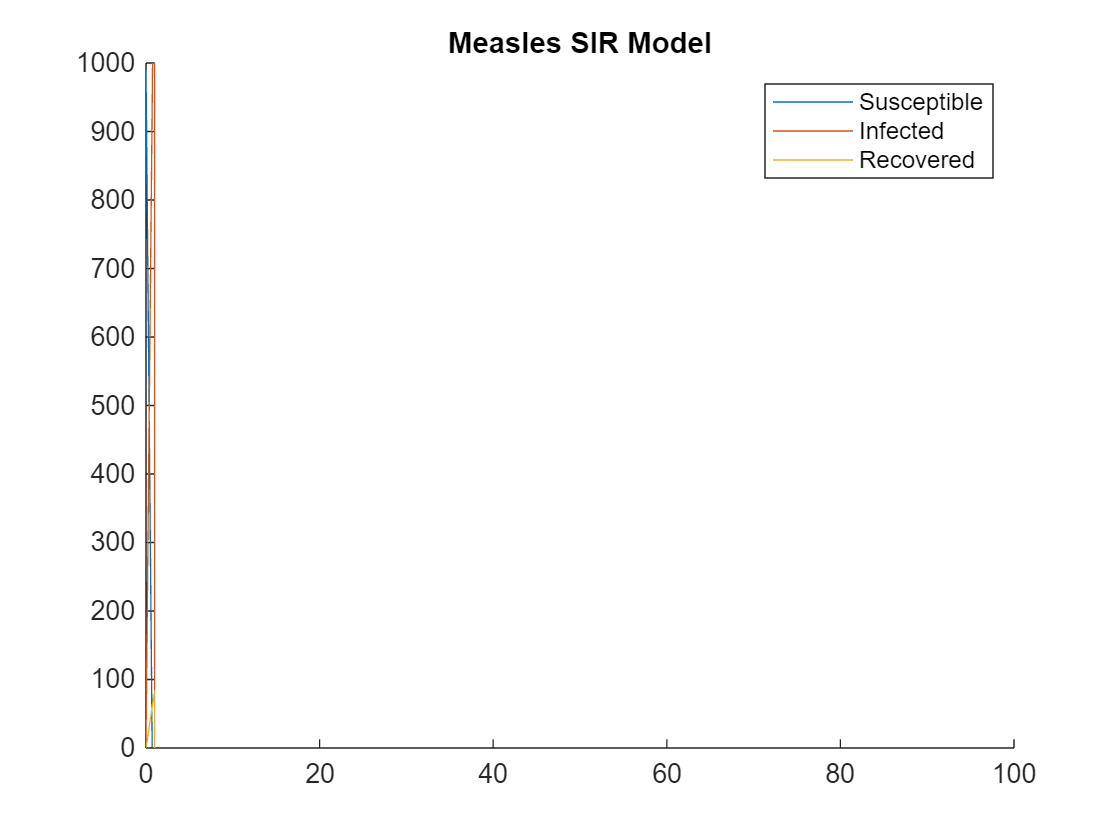


figure(3)
hold on
title('Measles SIR Model')
plot(Time,Measles_S)
plot(Time,Measles_I)
plot(Time,Measles_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000])
hold off